clear;
clc;
close all;
mainFolder = pwd;
addpath(genpath(mainFolder))

exportgraphics = 値をもつ function_handle :
    @(x)error('exportgraphics')


## Approximation of l2norm evaluation and Approximation error

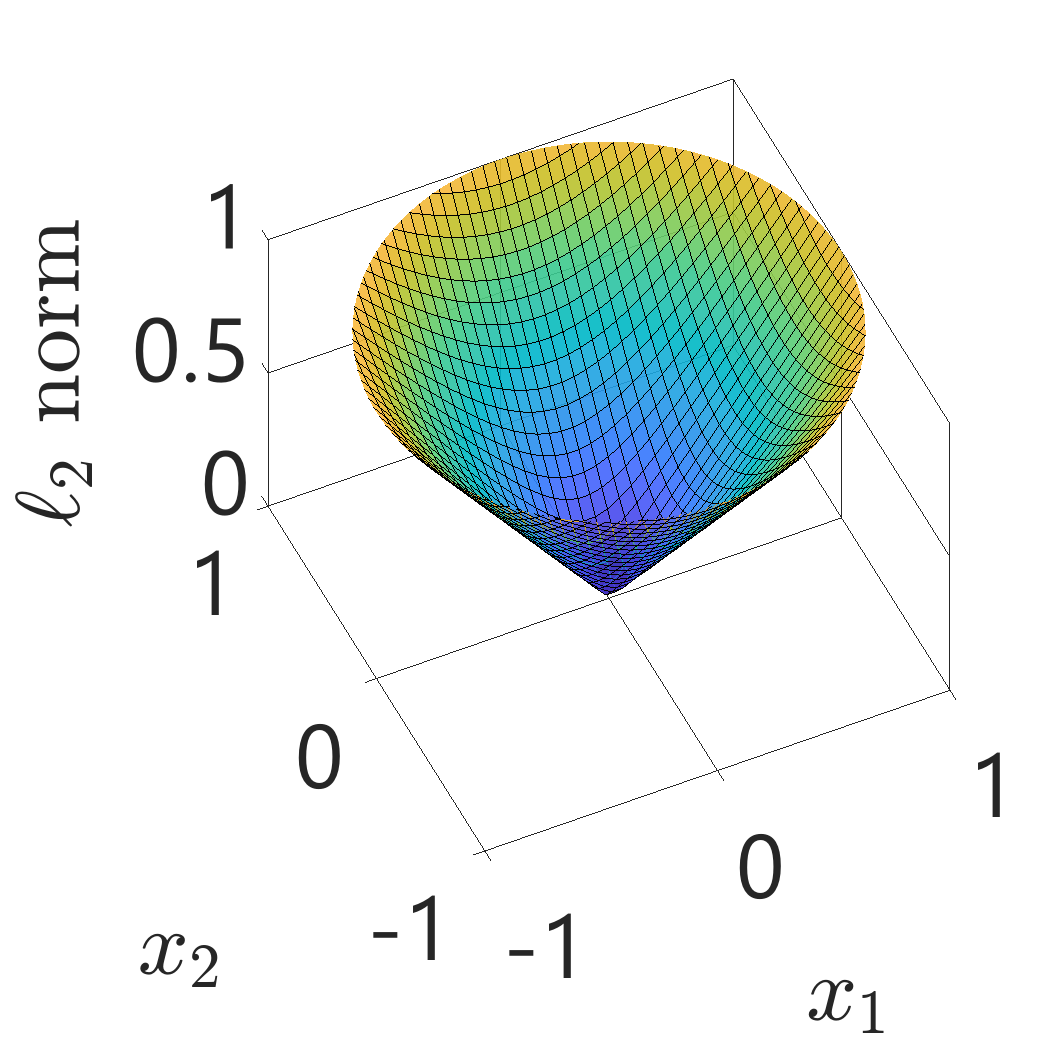

次を使用中のエラー: main>@(x)error('exportgraphics')
入力引数が多すぎます。

エラー: plot_l2norm (行 19)
exportgraphics(fig_handle,imagesavefolder+'l2_ex.png',"Resolution",resolution);

エラー: run (行 112)
evalin('caller', strcat(scr

cd l2norm_MATLAB/compare_proposal/compare_in_fig/
run('plot_l2norm.m')

image_name = {'l2_1.png', 'l2_1_diff.png', 'l2_2.png', 'l2_2_diff.png', ...
    'l2_3.png', 'l2_3_diff.png', 'l2_4.png', 'l2_4_diff.png', 'l2_ex.png'};
images = cell(1, length(image_name));
for i = 1:length(image_name)
    images{i} = imread(image_name{i});
end
montage(images)
cd(mainFolder)

## Soft-thresholding function of the generalized soft-thresholding and Approximate error

cd l2norm_MATLAB/compare_proposal/compare_in_fig/
run('plot_softthr.m')
image_name = {'staprox04.png', 'staprox04_diff.png', 'staprox08.png', 'staprox08_diff.png', ...
    'staprox12.png', 'staprox12_diff.png', 'staprox16.png', 'staprox16_diff.png', 'srexct.png'};
images = cell(1, length(image_name));
for i = 1:length(image_name)
    images{i} = imread(image_name{i});
end
montage(images)
cd(mainFolder)

## Function of HW costs with metavariables $\beta$ and $\gamma$

cd l2norm_MATLAB/mathematical/
run('mathfunc.mlx')
cd(mainFolder)

## Function plots of the reference and the approximation algorithm

cd l2norm_MATLAB/compare_proposal/compare_in_fig/
run('compare_withpsnr.m')
cd(mainFolder)

## Simulation results of isotropic TV regularization

Select $\sigma$ = 5/255, 10/255, 15/255, 20/255 and images when running the model for the proposed method. 

Select you

cd l2norm_MATLAB/TV/TEST_DATA/
sigma = 10/255;
img1 = imread("cameraman.tif");
run('make_pix_loss_test_data.m')
cd(mainFolder)

N = 1 is the calculation of sqrt (x^2 + y^2), N = 2,3,4 when running the model ('tv_system_sq2_4.slx') for the proposed method.

N = 5,6 is PCA Np = 10,50. N = 7 is CORDIC.

Select you

niter = 1;
cd l2norm_MATLAB/TV/
run('main_pixloss.m')
if niter == 1
    image_name = {'result/TV_orgImg.png', 'result/TV_noisy.png', 'result/TV_restored_exact.png'};
elseif niter == 2
    image_name = {'result/TV_orgImg.png', 'result/TV_noisy.png', 'result/TV_restored_sq2.png'};
elseif niter == 3
    image_name = {'result/TV_orgImg.png', 'result/TV_noisy.png', 'result/TV_restored_sq3.png'};
elseif niter == 4
    image_name = {'result/TV_orgImg.png', 'result/TV_noisy.png', 'result/TV_restored_sq4.png'};
elseif niter == 5
    image_name = {'result/TV_orgImg.png', 'result/TV_noisy.png', 'result/TV_restored_pca10.png'};
elseif niter == 6
    image_name = {'result/TV_orgImg.png', 'result/TV_noisy.png', 'result/TV_restored_pca50.png'};
elseif niter == 7
    image_name = {'result/TV_orgImg.png', 'result/TV_noisy.png', 'result/TV_restored_cordic.png'};
end

images = cell(1, length(image_name));
for i = 1:length(image_name)
    images{i} = imread(image_name{i});
end
montage(images)
fileID = fopen('result/mse.txt', 'r');
fileContent = fscanf(fileID, '%c');
fprintf('%s\n', fileContent);
fclose(fileID);
cd(mainFolder)

## Simulation results of image restration for an artificial stripe pattern

cd l2norm_MATLAB/TV/
run('angleplot.m')
cd(mainFolder)

# FPGA implemantation

### Simulation results of the computational accuracy of the proposed method and the fixed-point implementation of the existing method evaluated in term of MSE

- The results of running the Simulink model are saved as .mat files in the resultw folder

cd l2norm_FPGA_project/
run('result_mse.m')

- The figure1 show *F*max, which is the maximum operable frequency of FPGA

- The figure2 show latency, which is the time taken from the first input to the first output

- The figure3 show the evaluated maximum time from one output to the next one, i.e., the reciprocal of throughputs 

- .txt file of the maximum operating frequency exists in the fmax folder

- Create a project from Vitis Model Composer and perform Synthesis and Implementation in Vivado

run('result_fmax.m')

## Synthesis reportswith respect to the circuit area (LUTs and FFs)

- Create a project from Vitis Model Composer and perform Synthesis and Implementation in Vivado

- The results of running the Simulink model are saved as .mat files in the resultw folder

run('result_area.m')
cd(mainFolder)